## LFM的仿真

@Copyright (c) zihan xing

发射信号参数

clc;clear;close all;
addpath('funcs');  % 将 functions 文件夹添加到路径
fs = 4e3;
fc = 1.5e3;
Ts = 1/fs;
B = 200;    % 带宽（Hz）
f_begin =  1.4e3;%最低频率
f_end =    1.6e3;%最高频率

### LFM信号

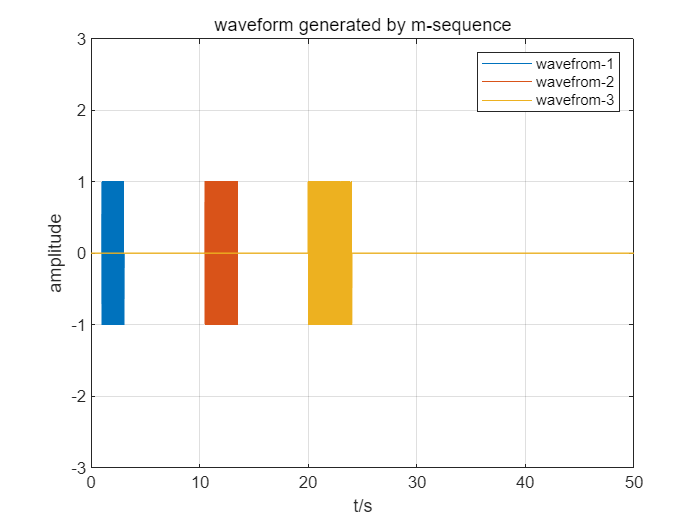


Tp1 = 2;                %第一个脉冲的长度
Tp2 = 3;
Tp3 = 4;              
t1 = 0:1/fs:Tp1/2-1/fs;
t2 = 0:1/fs:Tp2/2-1/fs;
t3 = 0:1/fs:Tp3/2-1/fs;
k1 = B/(Tp1/2);k2 = B/(Tp2/2);k3 = B/(Tp3/2);
lfm1 = exp(1j*2*pi*(f_begin*t1+0.5*k1*t1.^2));  %三个时宽不同的lfm脉冲
lfm1  = [lfm1 exp(1j*2*pi*(f_end*t1-0.5*k1*t1.^2))];

matchedFilter1 = lfm1;%匹配滤波器
lfm1_paddle = [zeros(1,(Tp3-Tp1)/2*fs) ,lfm1,zeros(1,(Tp3-Tp1)/2*fs) ];

lfm2 = exp(1j*2*pi*(f_begin*t2+0.5*k2*t2.^2));
lfm2  = [lfm2 exp(1j*2*pi*(f_end*t2-0.5*k2*t2.^2))];

matchedFilter2 = lfm2;
lfm2_paddle = [zeros(1,(Tp3-Tp2)/2*fs) ,lfm2,zeros(1,(Tp3-Tp2)/2*fs) ];

lfm3 = exp(1j*2*pi*(f_begin*t3+0.5*k3*t3.^2));
lfm3 = [lfm3 exp(1j*2*pi*(f_end*t3-0.5*k3*t3.^2))];
matchedFilter3 = lfm3;


TIME = 250;
paddled1 = [lfm1_paddle zeros(1,round(TIME*fs)-round(Tp3*fs))];                    %1~3s存在信号
paddled2  = [zeros(1,10*fs) lfm2_paddle zeros(1,round((TIME-10)*fs)-round(Tp3*fs))];%10.5~13.5S存在信号
paddled3  = [zeros(1,20*fs) lfm3 zeros(1,round((TIME-20)*fs)-round(Tp3*fs))];%20~24s存在信号


% 定义时间参数
t = (0:1/fs:TIME - 1/fs).'; % 时间向量，这里生成0到100秒的时间序列，采样间隔为1/fs
N = length(t);

figure
plot(t, real(paddled1));hold on;
plot(t, real(paddled2));hold on;
plot(t, real(paddled3));hold on;
xlabel('t/s');ylabel('amplitude');title('waveform generated by m-sequence');
grid on;legend('wavefrom-1','wavefrom-2','wavefrom-3');
axis([0,50,-3,3]);


%计算三个波形的能量
E1 = 20*log10(sum(abs(lfm1).^2)./1e-6);
E2 = 20*log10(sum(abs(lfm2).^2)./1e-6);
E3 = 20*log10(sum(abs(lfm3).^2)./1e-6);
disp(E1);disp(E2);disp(E3);

  198.0618

  201.5836

  204.0824



时频图

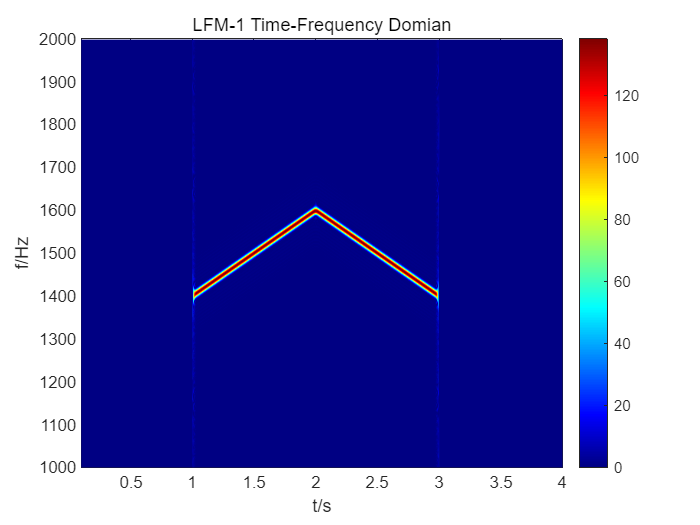

%信号的时频
begin_time = 0.1;
end_time = 4;
buffer = paddled1(round(begin_time*fs):round(end_time*fs));
N = 1024;
[R,T,F] = tfrpwv(buffer.',1:length(buffer),N,hamming(odd(N/4)),0);
T = T/fs+ones(1,length(T)).*begin_time;
F = F*fs;

figure
pcolor(T,F,abs(R));
shading interp;
colormap('jet');
colorbar;
xlabel('t/s');ylabel('f/Hz');
axis([-inf,inf,1000,2000]);
title('LFM-1 Time-Frequency Domian');

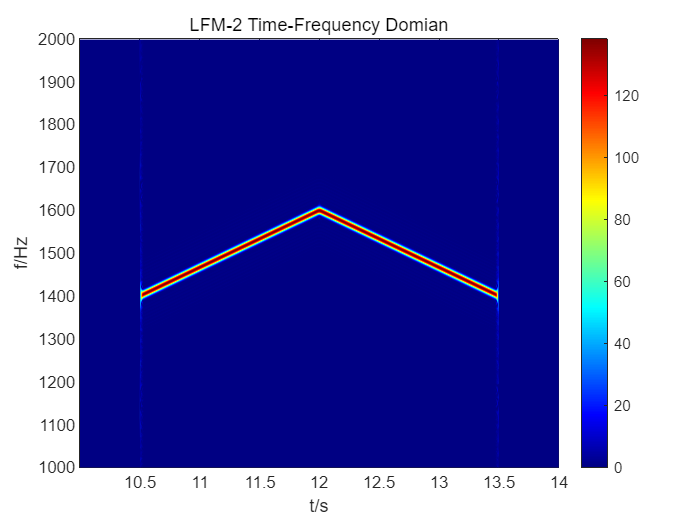

%信号的时频
begin_time = 10;
end_time = 14;
buffer = paddled2(round(begin_time*fs):round(end_time*fs));
N = 1024;
[R,T,F] = tfrpwv(buffer.',1:length(buffer),N,hamming(odd(N/4)),0);
T = T/fs+ones(1,length(T)).*begin_time;
F = F*fs;

figure
pcolor(T,F,abs(R));
shading interp;
colormap('jet');
colorbar;
xlabel('t/s');ylabel('f/Hz');
axis([-inf,inf,1000,2000]);
title('LFM-2 Time-Frequency Domian');

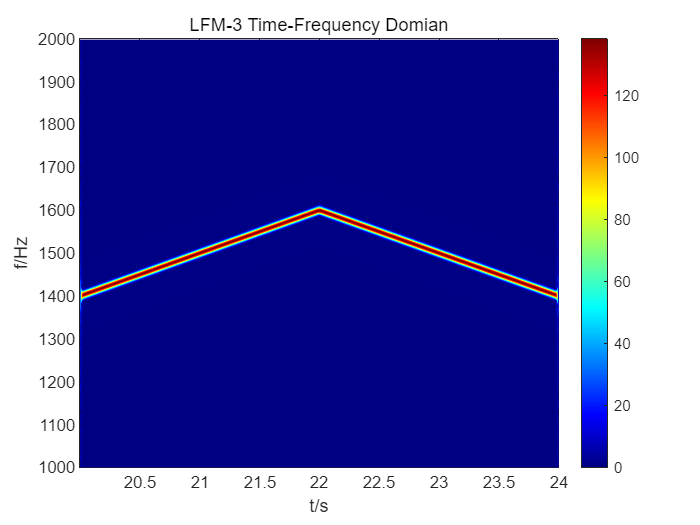

%信号的时频
begin_time = 20;
end_time = 24;
buffer = paddled3(round(begin_time*fs):round(end_time*fs));
N = 1024;
[R,T,F] = tfrpwv(buffer.',1:length(buffer),N,hamming(odd(N/4)),0);
T = T/fs+ones(1,length(T)).*begin_time;
F = F*fs;

figure
pcolor(T,F,abs(R));
shading interp;
colormap('jet');
colorbar;
xlabel('t/s');ylabel('f/Hz');
axis([-inf,inf,1000,2000]);
title('LFM-3 Time-Frequency Domian');

## 绘制模糊函数

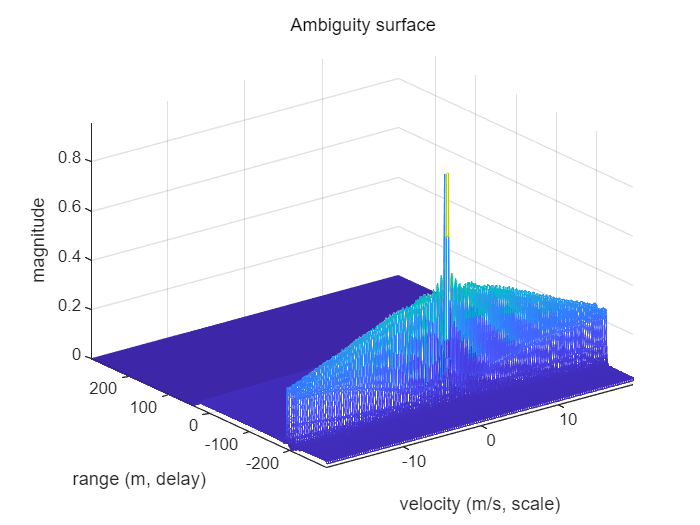

r=50;b=2;len=7;
c = 1500;                           %参考速度为1500
vmin = -20; vmax = 20;              %定义速度范围
velt= 0*c/(r*(b^len-1));            %速度为0，无多普勒 
etat = 1+(velt/c);                  %(1+v/c)用来计算经多普勒频移后的频率的比值
[pt,qt] = rat(etat);                %获取(1+v/c)的分子和分母
rs_bsig1 = resample(lfm1_paddle,pt,qt);%对信号进行重采样
% delay
N = size(rs_bsig1,2);               %获取重采样的信号大小
delay = round((1000/c)*fs);         %TO DO:?????
obsvN = delay+N;                    %obsvN 总的观测的长度
s_n = [rs_bsig1 zeros(1,obsvN-N)];  %s_n 在原始信号后面补零
sig = s_n(1:obsvN-delay);           %截取的信号
bsig_no = [zeros(1,delay) sig];     %对sig添加延迟

clear obsvN sig N;

vel_del = c/(r*(b^len-1));          % vel_del 速度分辨率
vel = 0:vel_del:vmax;               
vel = [-vel(end:-1:2) vel];         % vel 速度范围：其中存储的是不同的速度，包括正负值
eta = 1+(vel/c);                    %获取(1+v/c)的分子和分母
[p,q]= rat(eta);                    

ambig1 = cell(1, length(vel));      %初始化两个cell数组
ambig2 = cell(1, length(vel));
ambig3 = cell(1, length(vel));

for i =1:length(vel)  % 遍历vel速度数组
    re_samp_bsig1 = resample(lfm1_paddle,p(i),q(i));     % p>q expansion and p<q compression
    re_samp_bsig2 = resample(lfm2_paddle,p(i),q(i));
    re_samp_bsig3 = resample(lfm3,p(i),q(i));
    
    % --------在时域上进行相关处理----------------------------------- 
    if length(re_samp_bsig1)>length(bsig_no)   %如果重采样后的信号长度大于延迟信号，补零以匹配长度。
        na = length(re_samp_bsig1)-length(bsig_no);
        bsig_no= [bsig_no zeros(1,na+1)];
    end
    ambig1{i}=  abs(matchFilter(bsig_no,re_samp_bsig1,'none'));
    nl = length(bsig_no);
    ambigh1(1:(nl),i) =(ambig1{i});

    if length(re_samp_bsig2)>length(bsig_no)
        na = length(re_samp_bsig2)-length(bsig_no);
        bsig_no= [bsig_no zeros(1,na+1)];
    end     
    ambig2{i}=  abs(matchFilter(bsig_no,re_samp_bsig2,'none'));
    nl = length(bsig_no);
    ambigh2(1:(nl),i) =(ambig2{i});

    if length(re_samp_bsig3)>length(bsig_no)   %如果重采样后的信号长度大于延迟信号，补零以匹配长度。
        na = length(re_samp_bsig3)-length(bsig_no);
        bsig_no= [bsig_no zeros(1,na+1)];
    end
    ambig3{i}=  abs(matchFilter(bsig_no,re_samp_bsig3,'none'));
    nl = length(bsig_no);
    ambigh3(1:(nl),i) =(ambig3{i});


end

Max1= max(max(ambigh1));Max2= max(max(ambigh2));Max3= max(max(ambigh3));
A1=(abs(ambigh1 ./ Max1));A2=(abs(ambigh2 ./ Max2));A3 = (abs(ambigh3 ./ Max3));

%重采样模糊函数
%% resample the ambiguity funnction;
for i =1:length(vel)
    re_ambigh1(:,i)=resample(A1(:,i),1,6.);
    re_ambigh2(:,i)=resample(A2(:,i),1,6);
    re_ambigh3(:,i)=resample(A3(:,i),1,6);
end
A1=re_ambigh1;A2=re_ambigh2;A3=re_ambigh3;


figure;
N = length(A1); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A1);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;

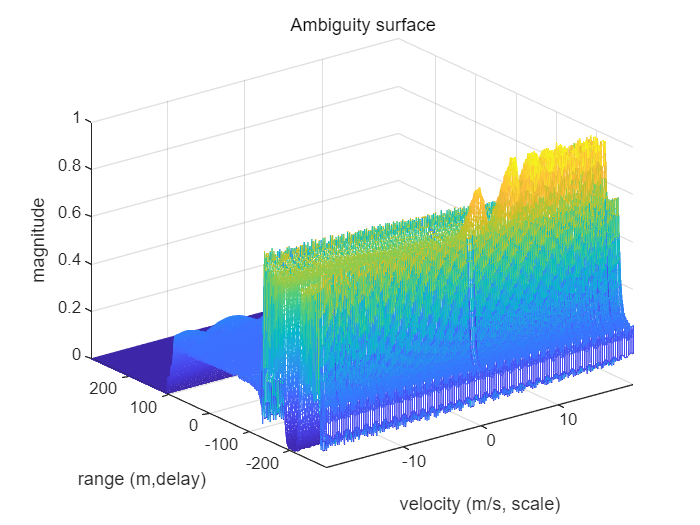

figure
N = length(A1); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A1);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;
view(0,90);colorbar;

figure;
N = length(A2); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A2);
xlabel('velocity (m/s, scale)');ylabel('range (m,delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight; 

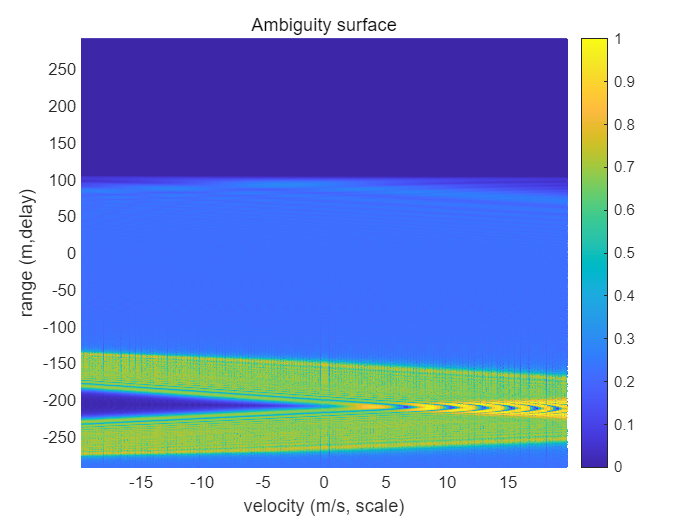

figure
N = length(A2); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A2);
xlabel('velocity (m/s, scale)');ylabel('range (m,delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;
view(0,90);colorbar;

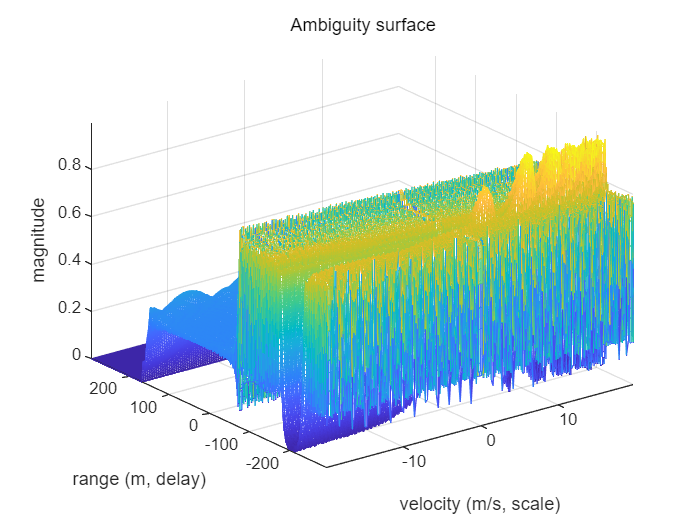

figure;
N = length(A3); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A3);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;

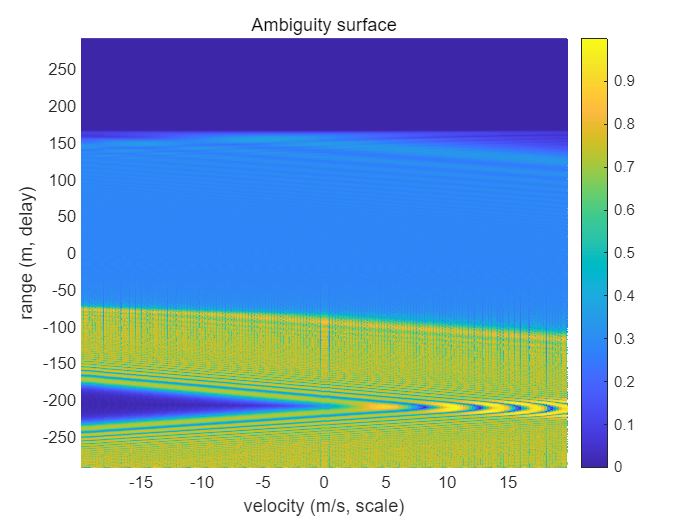

figure
N = length(A3); delay = 1:N; mesh(vel,((delay-N/2).*c)./(2*fs),A3);
xlabel('velocity (m/s, scale)');ylabel('range (m, delay)'); zlabel('magnitude');
title('Ambiguity surface'); axis tight;
view(0,90);colorbar;

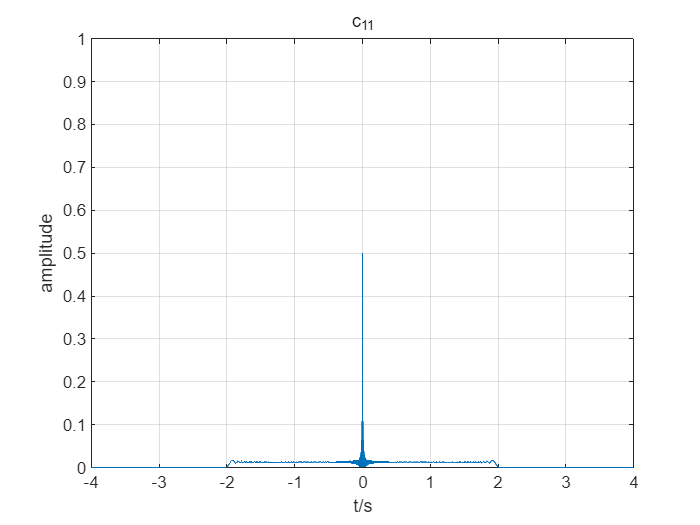

%计算相关函数
[c11,lags] = xcorr(lfm1_paddle ,lfm1_paddle);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
c11 = c11./length(lfm1_paddle);
figure
plot(lags*(1/fs),abs(c11));grid on;
xlabel('t/s');ylabel('amplitude');
title('c_{11}');ylim([0,1]);

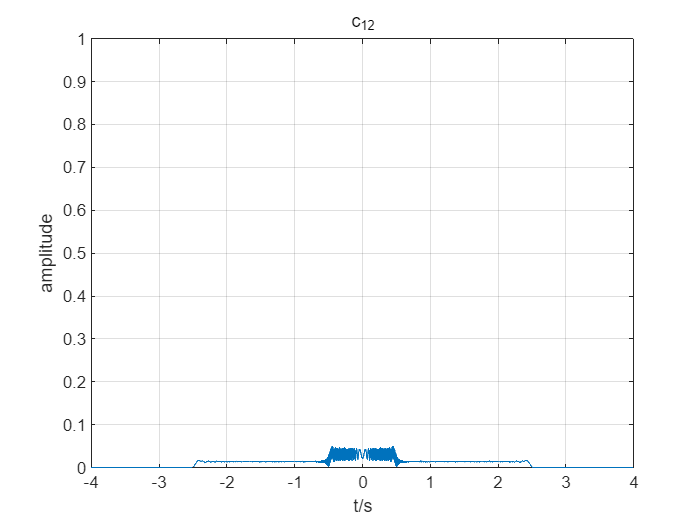


[c12,lags] = xcorr(lfm1_paddle ,lfm2_paddle);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
c12 = c12./length(lfm1_paddle);
figure
plot(lags*(1/fs),abs(c12));grid on;title('correlation-c12');ylim([0,1]);
xlabel('t/s');ylabel('amplitude');
title('c_{12}');ylim([0,1]);

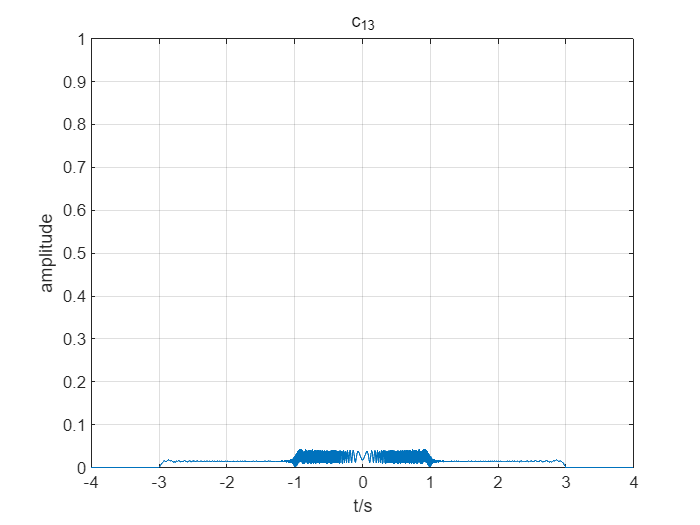


[c13,lags] = xcorr(lfm1_paddle ,lfm3);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
c13 = c13./length(lfm1_paddle);
figure
plot(lags*(1/fs),abs(c13));grid on;
title('c_{13}');ylim([0,1]);
xlabel('t/s');ylabel('amplitude');

## 信道

###  声速梯度


figure; 
bellhop MunkB_Coh;
plotssp('MunkB_Coh');

根据声速梯度图，当深度为200m时，声速为1530m/s

###     传播损失

%计算传播损失
bellhop 'envs/MunkB_Coh';
figure
plotshd('envs/MunkB_Coh.shd');

绘制声线

figure
bellhop MunkB_ray;
plotray('envs/MunkB_ray.ray');

发射点深度：200m

- 直达区：接收点深度3000m，距离12000

- 第一声影区：接收点深度200m，距离22933m

- 第一会聚区：接收点深度200m，距离58954m

- 第二声影区：接收点深度200m，距离92986m

- 第二会聚区：接收点深度200m，距离119720m

- 第三声影区：接收点深度200m，距离155110m

- 第三会聚区：接收点深度200m，距离180196m

### 信道的脉冲响应

bellhop计算脉冲响应

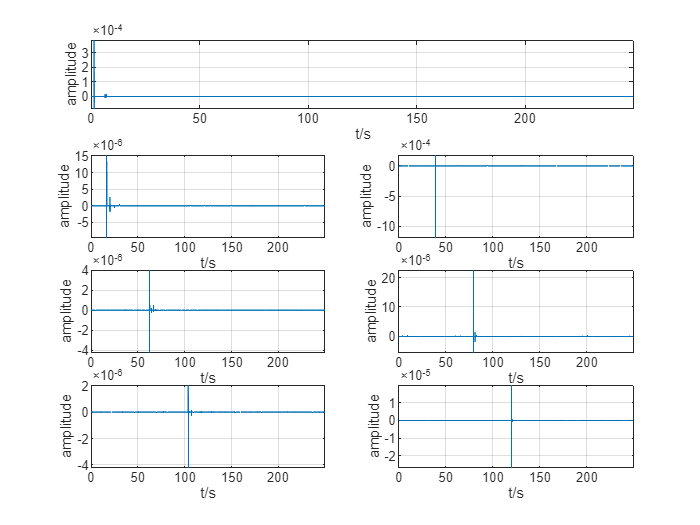

bellhop('envs/direct_Arr');                 %直达区
[direct_arr, ~ ] = read_arrivals_asc('envs/direct_Arr.arr');

bellhop('envs/shadow1_Arr');                %第一声影区
[shadow1_arr, ~ ] = read_arrivals_asc('envs/shadow1_Arr.arr');

bellhop('envs/convergence1_Arr');           %第一会聚区
[convergence1_arr, ~ ] = read_arrivals_asc('envs/convergence1_Arr.arr');
 
bellhop('envs/shadow2_Arr');                %第二声影区
[shadow2_arr, ~ ] = read_arrivals_asc('envs/shadow2_Arr.arr');

bellhop('envs/convergence2_Arr');           %第二会聚区
[convergence2_arr, ~ ] = read_arrivals_asc('envs/convergence2_Arr.arr');

bellhop('envs/shadow3_Arr');                %第三声影区
[ shadow3_arr, ~ ] = read_arrivals_asc('envs/shadow3_Arr.arr');

bellhop('envs/convergence3_Arr');           %第三会聚区
[convergence3_arr, ~ ] = read_arrivals_asc('envs/convergence3_Arr.arr');

t = 0:1/fs:TIME - 1/fs; % 时间向量，这里生成0到200秒的时间序列，采样间隔为1/fs

%获取脉冲响应
%fs：采样频率，时间长度260s

direct_IR = get_IR(direct_arr, fs, TIME);            %直达区脉冲响应
direct_TF = fftshift(fft(direct_IR)).';

shadow1_IR = get_IR(shadow1_arr, fs, TIME);          %第一声影区脉冲响应
shadow1_TF = fftshift(fft(shadow1_IR)).';

convergence1_IR = get_IR(convergence1_arr, fs, TIME); %第一会聚区脉冲响应
convergence1_TF = fftshift(fft(convergence1_IR)).';

shadow2_IR = get_IR(shadow2_arr, fs, TIME);           %第二声影区脉冲响应
shadow2_TF = fftshift(fft(shadow2_IR)).';

convergence2_IR = get_IR(convergence2_arr, fs, TIME); %第二会聚区脉冲响应
convergence2_TF = fftshift(fft(convergence2_IR)).';

shadow3_IR = get_IR(shadow3_arr, fs, TIME);           %第二声影区脉冲响应
shadow3_TF = fftshift(fft(shadow3_IR)).';

convergence3_IR = get_IR(convergence3_arr, fs, TIME); %第二会聚区脉冲响应
convergence3_TF = fftshift(fft(convergence3_IR)).';

N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
figure
subplot(4,1,1)
plot(t,direct_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,3)
plot(t,shadow1_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,4)
plot(t,convergence1_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,5)
plot(t,shadow2_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,6)

plot(t,convergence2_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;
subplot(4,2,7)
plot(t,shadow3_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

subplot(4,2,8)
plot(t,convergence3_IR);grid on;xlabel('t/s');ylabel('amplitude');axis tight;

工具箱绘制脉冲响应

plotarr('direct_Arr.arr',1,1,1);
plotarr('shadow1_Arr.arr',1,1,1);
plotarr('convergence1_Arr.arr',1,1,1);
plotarr('shadow2_Arr.arr',1,1,1);
plotarr('convergence2_Arr.arr',1,1,1);


## 仿真亮点模型

R为鱼雷与潜艇距离,即鱼雷与代表艇尾的亮点距离;0为照射角;表示该亮点与艇艉的距离

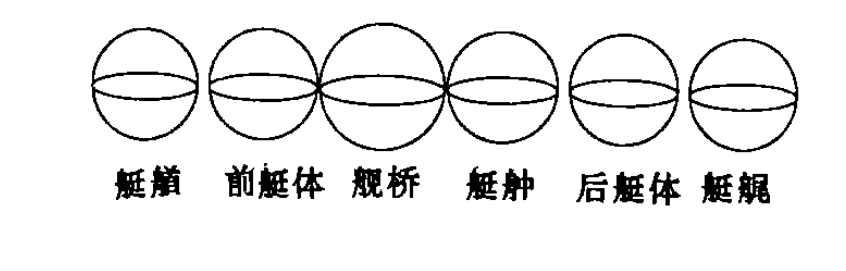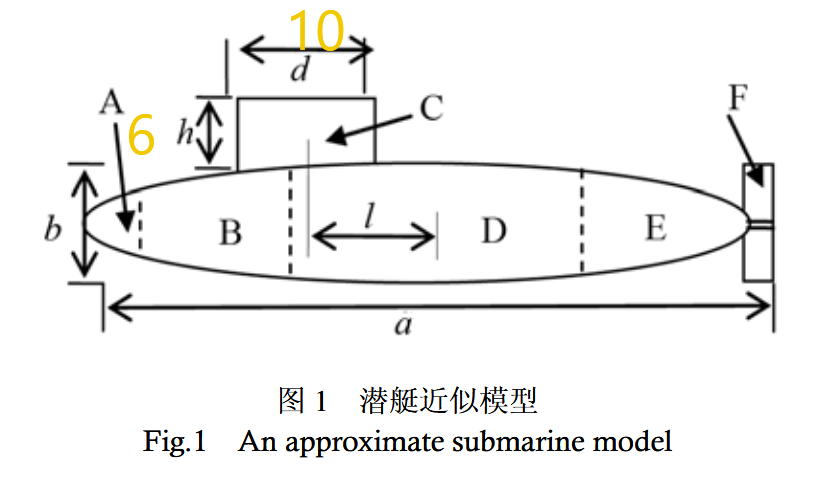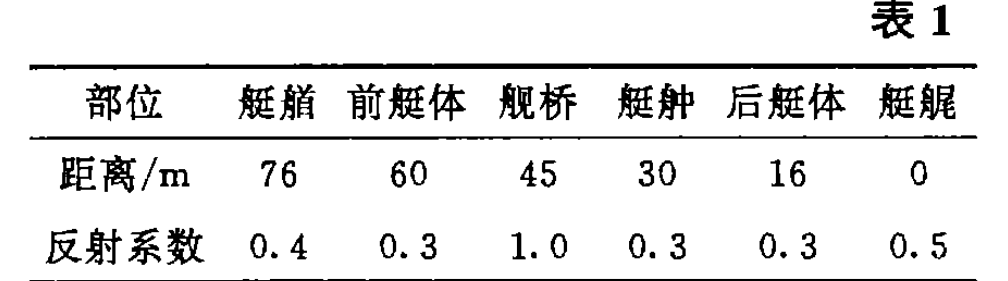

亮点模型各个亮点的时延：$\tau_i = \frac{2\sqrt{(L_icos\theta)^2+(L_isin\theta)^2}}{c}$

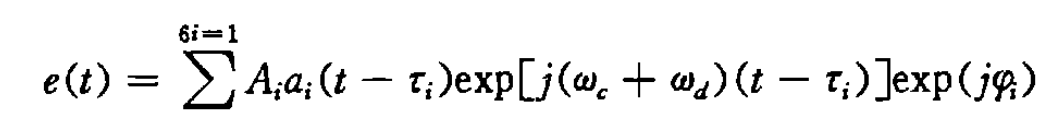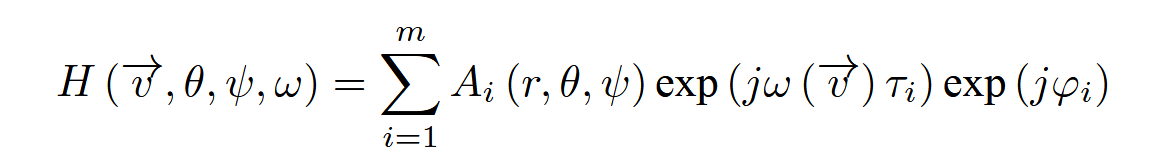

L = [76,   60,     45,   30,   16,   0]; 
b = [0.4, 0.3, 1.0, 0.3, 0.3, 0.5];% 定义距离和反射系数
r = [7,7,8,7,7,7];

c = 1530;    %深度1000m 声速1500m/s
N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
theta = 90;
phi = pi;

TF_highlight = get_highlight_TF(c,fs,N,theta,L,b,r).';


绘制亮点的转移函数和脉冲响应

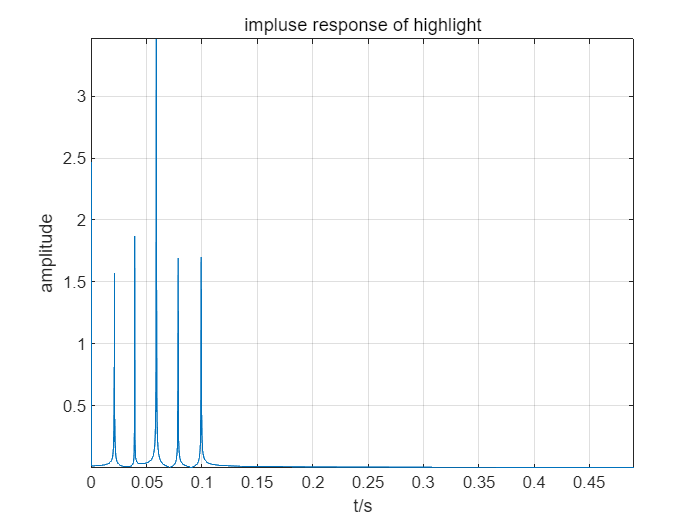

figure
% subplot(2,1,2);
% plot(f,abs(TF_highlight));xlabel('f/Hz');ylabel('幅度');grid on;title('亮点模型转移函数');

% axis(-fs/2,fs/2,0,inf);
IR_Highlight = ifft(fftshift(TF_highlight));
% subplot(2,1,1);
time = 0.49;
plot(t,abs(IR_Highlight));xlabel('t/s');ylabel('amplitude');grid on;title('impluse response of highlight');
axis([0,time,-inf,inf]);
clear IR_Highlight;

s1_f = fftshift(fft(paddled1.')).*direct_TF.*TF_highlight;%经过信道到达目标

s2_f = fftshift(fft(paddled1).').*shadow1_TF.*TF_highlight;%目标的转移函数

s3_f = fftshift(fft(paddled1).').*convergence1_TF.*TF_highlight;%目标的转移函数

s4_f = fftshift(fft(paddled1).').*shadow2_TF.*TF_highlight;%目标的转移函数

s5_f = fftshift(fft(paddled1).').*convergence2_TF.*TF_highlight;%目标的转移函数

s6_f = fftshift(fft(paddled1).').*shadow3_TF.*TF_highlight;%目标的转移函数

s7_f = fftshift(fft(paddled1).').*convergence3_TF.*TF_highlight;%目标的转移函数

clear P1 P2 P3;
clear  TF_highlight L b R;

## 信号返回发射点：

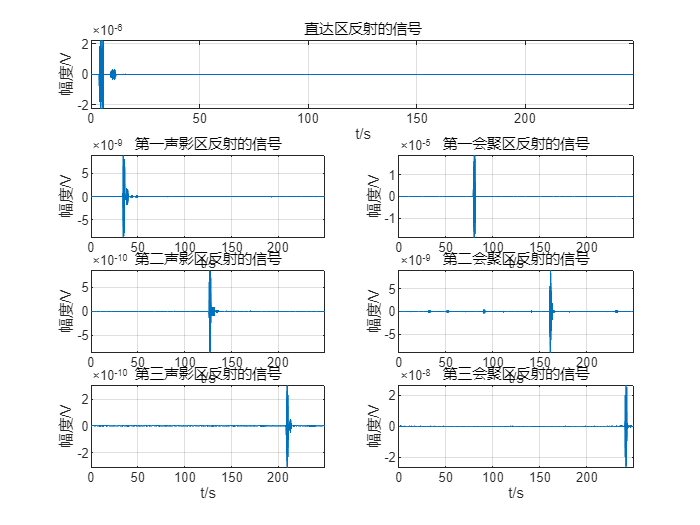

temp = s1_f.*direct_TF;
s1 = ifft(fftshift(temp)).';%交换变量

temp = s2_f.*shadow1_TF;
s2 = ifft(fftshift(temp)).';%交换变量

temp = s3_f.*convergence1_TF;
s3 = ifft(fftshift(temp)).';%交换变量

temp = s4_f.*shadow2_TF;
s4 = ifft(fftshift(temp)).';%交换变量

temp = s5_f.*convergence2_TF;
s5 = ifft(fftshift(temp)).';%交换变量

temp = s6_f.*shadow3_TF;
s6 = ifft(fftshift(temp)).';%交换变量

temp = s7_f.*convergence3_TF;
s7 = ifft(fftshift(temp)).';%交换变量
clear s1_f s2_f s3_f s4_f s5_f s6_f s7_f;
figure
subplot(4,1,1)
plot(t,real(s1));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('直达区反射的信号'));
subplot(4,2,3)
plot(t,real(s2));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('第一声影区反射的信号'));
subplot(4,2,4)
plot(t,real(s3));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('第一会聚区反射的信号'));
subplot(4,2,5)
plot(t,real(s4));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('第二声影区反射的信号'));
subplot(4,2,6)
plot(t,real(s5));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('第二会聚区反射的信号'));

subplot(4,2,7)
plot(t,real(s6));xlabel('t/s');ylabel('幅度/V');grid on;axis tight;
title(sprintf('第三声影区反射的信号'));
subplot(4,2,8)
plot(t,real(s7));xlabel('t/s');ylabel('幅度/V');grid on;
title(sprintf('第三会聚区反射的信号'));axis tight;

## 添加噪声

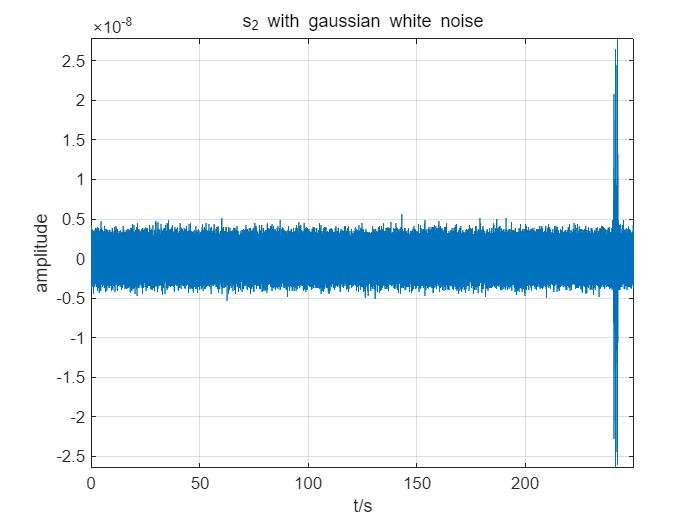

SNR = -5;       %设置信噪比 

s2_noisy = awgn(s2,SNR,'measured');s3_noisy = awgn(s3,SNR,'measured');
s4_noisy = awgn(s4,SNR,'measured');s5_noisy = awgn(s5,SNR,'measured');
s6_noisy = awgn(s6,SNR,'measured');s7_noisy = awgn(s7,SNR,'measured');
figure
plot(t,real(s7_noisy));xlabel('t/s');ylabel('amplitude');
grid on;title('s_2 with gaussian white noise');axis tight;

## 检测脉冲

根据能量进行检测

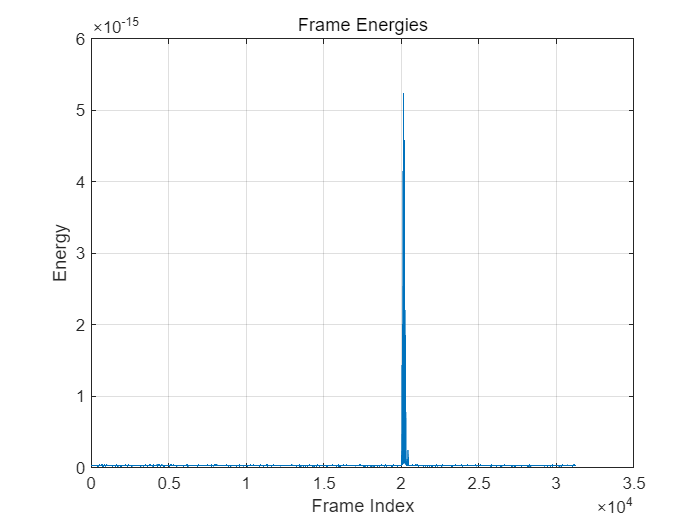

frame_length = 64;        % 帧长（样本点数）
frame_shift = 32;         % 帧移（样本点数）

num_frames = floor(length(s2_noisy) / frame_shift) - 1;  % 计算帧的数量
frame_energies2 = get_frame_energy(s2_noisy,frame_length,frame_shift);
frame_energies3 = get_frame_energy(s3_noisy,frame_length,frame_shift);
frame_energies4 = get_frame_energy(s4_noisy,frame_length,frame_shift);
frame_energies5 = get_frame_energy(s5_noisy,frame_length,frame_shift);
frame_energies6 = get_frame_energy(s6_noisy,frame_length,frame_shift);

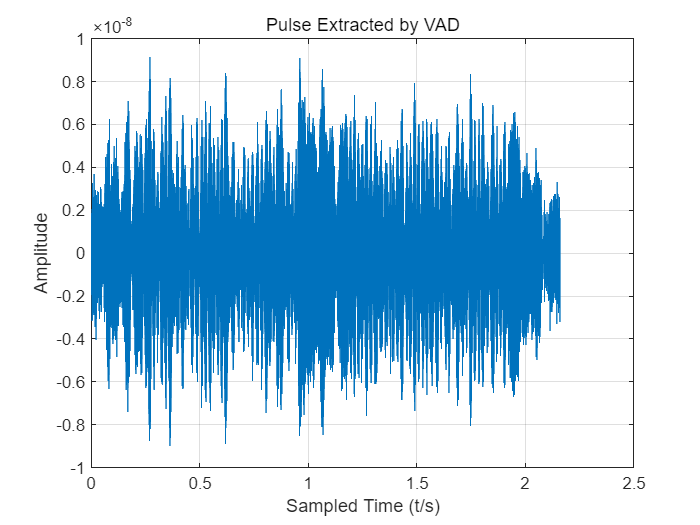

frame_energies7 = get_frame_energy(s7_noisy,frame_length,frame_shift);

% 可视化每帧的能量
figure;
plot(frame_energies5);grid on;
title('Frame Energies');xlabel('Frame Index');ylabel('Energy');
threshold2 = 0.1*max(frame_energies2);  % 能量阈值（根据实验调整）
threshold3 = 0.1*max(frame_energies3);
threshold4 = 0.1*max(frame_energies4);
threshold5 = 0.1*max(frame_energies5);
threshold6 = 0.1*max(frame_energies6);
threshold7 = 0.1*max(frame_energies7);

%如果当前帧的能量大于阈值，获取该帧 
vad_sig2= detect_pulse(s2_noisy,frame_energies2,frame_shift,threshold2);
vad_sig3= detect_pulse(s3_noisy,frame_energies3,frame_shift,threshold3);
vad_sig4= detect_pulse(s4_noisy,frame_energies4,frame_shift,threshold4);
vad_sig5= detect_pulse(s5_noisy,frame_energies5,frame_shift,threshold5);
vad_sig6= detect_pulse(s6_noisy,frame_energies6,frame_shift,threshold6);

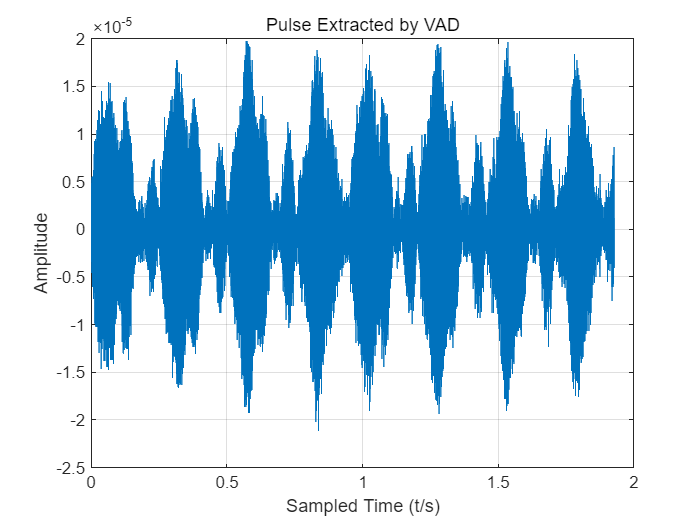

vad_sig7= detect_pulse(s7_noisy,frame_energies7,frame_shift,threshold7);
figure;
% 可视化提取的脉冲
plot(0:1/fs:(length(vad_sig2)-1)/fs,real(vad_sig2));grid on;

title('Pulse Extracted by VAD');
xlabel('Sampled Time (t/s)');ylabel('Amplitude');xlim auto;
% 可视化提取的脉冲
plot(0:1/fs:(length(vad_sig3)-1)/fs,real(vad_sig3));grid on;
title('Pulse Extracted by VAD');
xlabel('Sampled Time (t/s)');ylabel('Amplitude');xlim auto;

计算能量差

%计算提取的脉冲能量
E_vad2 = sum(abs(vad_sig2).^2);E_vad3 = sum(abs(vad_sig3).^2);
E_vad4 = sum(abs(vad_sig4).^2);E_vad5 = sum(abs(vad_sig5).^2);
E_vad6 = sum(abs(vad_sig6).^2);E_vad7 = sum(abs(vad_sig7).^2);

经过第一声影区传播损失为 150.8243dB 
 经过第一会聚区传播损失为 84.3336dB

经过第二声影区传播损失为 170.3993dB 
 经过第二会聚区传播损失为 151.8904dB

%计算能量损失

经过经过第三声影区传播损失为 180.6994dB 
 经过第三会聚区传播损失为 144.3016dB

TL2 = 10*log10(E2/E_vad2);TL3 = 10*log10(E2/E_vad3);
TL4 = 10*log10(E2/E_vad4);TL5 = 10*log10(E2/E_vad5);
TL6 = 10*log10(E2/E_vad6);TL7 = 10*log10(E2/E_vad7);
fprintf('经过第一声影区传播损失为 %.4fdB \n 经过第一会聚区传播损失为 %.4fdB',TL2,TL3);
fprintf('经过第二声影区传播损失为 %.4fdB \n 经过第二会聚区传播损失为 %.4fdB',TL4,TL5);
fprintf('经过经过第三声影区传播损失为 %.4fdB \n 经过第三会聚区传播损失为 %.4fdB',TL6,TL7);

发射点深度：200m

- 直达区：接收点深度3000m，距离12000

- 第一声影区：接收点深度200m，距离28916.6m

- 第一会聚区：接收点深度200m，距离58542m

- 第二声影区：接收点深度200m，距离92015m

- 第二会聚区：接收点深度200m，距离119720m

- 第三声影区：接收点深度200m，距离153902m

- 第三会聚区：接收点深度200m，距离178305m

采用过零检测

frame_length = 64;        % 帧长（样本点数）
frame_shift = 32;         % 帧移（样本点数）
num_frames = floor(length(s2_noisy) / frame_shift) - 1;  % 计算帧的数量
frames2 = framesig(s2_noisy,frame_length,OverlapLength=frame_shift);%将信号分成帧，每一列为一帧
frames3 = framesig(s3_noisy,frame_length,OverlapLength=frame_shift);%将信号分成帧，每一列为一帧
frames4 = framesig(s4_noisy,frame_length,OverlapLength=frame_shift);%将信号分成帧，每一列为一帧
frames5 = framesig(s5_noisy,frame_length,OverlapLength=frame_shift);%将信号分成帧，每一列为一帧
frames6 = framesig(s6_noisy,frame_length,OverlapLength=frame_shift);%将信号分成帧，每一列为一帧
frames7 = framesig(s7_noisy,frame_length,OverlapLength=frame_shift);%将信号分成帧，每一列为一帧

%计算每帧信号的过零率
zcr2 = get_zcr(frames2 , frame_length,num_frames);
zcr3 = get_zcr(frames3 , frame_length,num_frames);
zcr4 = get_zcr(frames4 , frame_length,num_frames);
zcr5 = get_zcr(frames5 , frame_length,num_frames);
zcr6 = get_zcr(frames6 , frame_length,num_frames);
zcr7 = get_zcr(frames7 , frame_length,num_frames);

% 设置过零率阈值
threshold = 0.2; % 这里只是示例，实际应用中需要根据情况调整

% 判断
isSpeech = zcr2 < threshold;

figure
stem(isSpeech);
xlabel('Frame Index');
ylabel('Is Speech (1 = Yes, 0 = No)');
title('Speech Detection based on Zero Crossing Rate');

## 波束形成

接收到的信号波束形成

考虑阵列情况

d = 1;                  % 阵元间距（10m长的线阵，共10个元素）
eleNum = 10;                 % 阵元数量
angles = -90:10:90;     % 角度范围 -90° 到 90°
alpha = 60;             %阵列的接收角度（0°~180°）

%% 仿真阵元域数据
t = 0:1/fs:TIME-1/fs; % 总时间向量

% beamformed_signals_time_domain1 = beamform(s1.',t,fs,d,c,eleNum,angles,alpha);
% beamformed_signals_time_domain2 = beamform(s2.',t,fs,d,c,eleNum,angles,alpha);
% beamformed_signals_time_domain3 = beamform(s3.',t,fs,d,c,eleNum,angles,alpha);
% beamformed_signals_time_domain4 = beamform(s4.',t,fs,d,c,eleNum,angles,alpha);
% beamformed_signals_time_domain5 = beamform(s5.',t,fs,d,c,eleNum,angles,alpha);
beamformed_signals_time_domain6 = beamform(s6.',t,fs,d,c,eleNum,angles,alpha);
beamformed_signals_time_domain7 = beamform(s7.',t,fs,d,c,eleNum,angles,alpha);

## 波束处理后的接收信号

波束角度60°

% s1_beam60 = beamformed_signals_time_domain1(7,:);
% s2_beam60 = beamformed_signals_time_domain2(7,:);
% s3_beam60 = beamformed_signals_time_domain3(7,:);
% s4_beam60 = beamformed_signals_time_domain4(7,:);
% s5_beam60 = beamformed_signals_time_domain5(7,:);
s6_beam60 = beamformed_signals_time_domain6(7,:);
s7_beam60 = beamformed_signals_time_domain7(7,:);
clear beamformed_signals_time_domain1 beamformed_signals_time_domain2 beamformed_signals_time_domain3;
clear beamformed_signals_time_domain4 beamformed_signals_time_domain5 beamformed_signals_time_domain6;
clear beamformed_signals_time_domain7;
clear s1 s2 s3 s4 s5 s6;
figure
subplot(3,1,1)
plot(t,real(s1_beam60));xlabel('t/s');ylabel('Am');grid on;
subplot(3,1,2)
plot(t,real(s2_beam60));xlabel('t/s');ylabel('Am');grid on;
subplot(3,1,3)
plot(t,real(s3_beam60));xlabel('t/s');ylabel('Am');grid on;

## 匹配滤波

时域信号

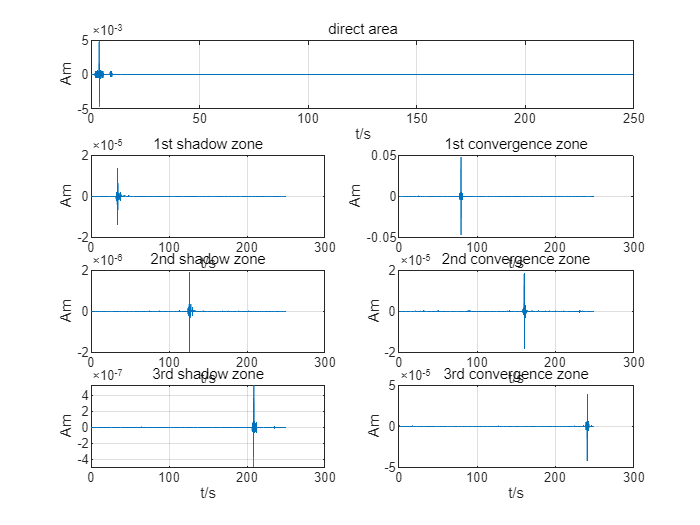


[r1,lags] = xcorr(s1 ,matchedFilter1);
idx = find(lags>=0,1);%找到第一个大于等于0的索引
r1 = r1(idx:end);
lags = lags(idx:end);    

[r2,~] = xcorr(s2,matchedFilter1);
r2 = r2(idx:end);

[r3,~] = xcorr(s3 ,matchedFilter1);
r3 = r3(idx:end);

[r4,~] = xcorr(s4 ,matchedFilter1);
r4 = r4(idx:end);

[r5,~] = xcorr(s5 ,matchedFilter1);
r5 = r5(idx:end);

[r6,~] = xcorr(s6 ,matchedFilter1);
r6 = r6(idx:end);

[r7,~] = xcorr(s7 ,matchedFilter1);
r7 = r7(idx:end);

clear  temp;

figure
subplot(4,1,1)
plot(lags*(1/fs),real(r1));xlabel('t/s');ylabel('Am');grid on;title('direct area');
subplot(4,2,3)
plot(lags*(1/fs),real(r2));xlabel('t/s');ylabel('Am');grid on;title('1st shadow zone');

subplot(4,2,4)
plot(lags*(1/fs),real(r3));xlabel('t/s');ylabel('Am');grid on;title('1st convergence zone');

subplot(4,2,5)
plot(lags*(1/fs),real(r4));xlabel('t/s');ylabel('Am');grid on;title('2nd shadow zone');
subplot(4,2,6)
plot(lags*(1/fs),real(r5));xlabel('t/s');ylabel('Am');grid on;title('2nd convergence zone');

subplot(4,2,7) 
plot(lags*(1/fs),real(r6));xlabel('t/s');ylabel('Am');grid on;title('3rd shadow zone');
subplot(4,2,8)
plot(lags*(1/fs),real(r7));xlabel('t/s');ylabel('Am');grid on;title('3rd convergence zone');
t = 0:1/fs:TIME-1/fs;
s1 = gather(r1);
s2 = gather(r2);
s3 = gather(r3);
clear r1 r2 r3;
% s1 = gather(s1_beam60);
% s2 = gather(s2_beam60);
% s3 = gather(s3_beam60);

时频

audiowrite('audios/lfm_direct.wav',real(s1)./max(abs(real(s1))),4e3);
audiowrite('audios/lfm_1st_shadow.wav',real(s2)./max(abs(real(s2))),4e3);
audiowrite('audios/lfm_1st_convergence.wav',real(s3)./max(abs(real(s3))),fs);
audiowrite('audios/lfm_2nd_shadow.wav',real(s4)./max(abs(real(s4))),fs);
audiowrite('audios/lfm_2nd_convergence.wav',real(s5)./max(abs(real(s5))),fs);
audiowrite('audios/lfm_3rd_shadow.wav',real(s6)./max(abs(real(s6))),fs);
audiowrite('audios/lfm_3rd_convergence.wav',real(s7)./max(abs(real(s7))),fs);